%% 1. CONFIGURAZIONE
% Nome della variabile SimulationOutput nel workspace
simOutputVarName = 'out';

% Nomi segnali (Lasciare vuoto '' se assente)
signal_names.js_cmd   = 'q_cmd';      % [t, q1, q2, q3]
signal_names.js_sim   = 'q_sim';      % [t, q1, q2, q3]
signal_names.js_hw    = 'q_actual';   % [t, q1, q2, q3]

signal_names.cs_cmd   = 'p_cmd';      % [t, x, y, z]
signal_names.cs_sim   = 'p_sim';      % [t, x, y, z]
signal_names.cs_hw    = 'p_actual';   % [t, x, y, z]
signal_names.cs_full  = 'p_full';     % [t, x, y, z]

signal_names.obstacle = 'obstacle height'; % [t, z]

% Plotting Config
T_cycle = 2;             
num_cycles_to_plot = 5;  

% Limiti Giunti (Gradi, verranno usati dopo conversione)
joint_limits = struct();
joint_limits.q1 = [-30, 30]; 
joint_limits.q2 = [-90, 90]; 
joint_limits.q3 = [30, 180]; 

% Salvataggio
save_figures = true; 
save_path = '../TESI/images3/'; 

%% 2. ESTRAZIONE DATI
fprintf('Inizio estrazione...\n');

Inizio estrazione...



if ~exist(simOutputVarName, 'var')
    error("Oggetto '%s' non trovato.", simOutputVarName);
end
try
    logsout_dataset = eval([simOutputVarName, '.logsout']);
catch
    error("Impossibile accedere a logsout.");
end

data = struct(); 
fields_to_find = fieldnames(signal_names);

for k = 1:length(fields_to_find)
    key = fields_to_find{k};
    sig_name = signal_names.(key);
    
    if isempty(sig_name), continue; end
    
    try
        sig_obj = logsout_dataset.getElement(sig_name);
        ts = sig_obj.Values;
        time_row = ts.Time';
        data_val = ts.Data;
        
        num_samples = length(time_row);
        sz = size(data_val);
        
        num_elements = numel(data_val);
        num_ch = num_elements / num_samples;
        
        if sz(1) == num_samples
            data_rows = reshape(data_val, num_samples, num_ch).';
        elseif sz(end) == num_samples
            data_rows = reshape(data_val, num_ch, num_samples);
        else
            fprintf('Dimensione errata per %s. Saltato.\n', sig_name);
            continue;
        end
        
        data.(key) = [time_row; data_rows];
        fprintf('Estratto: %s -> %dx%d\n', key, size(data.(key), 1), size(data.(key), 2));
        
    catch
        fprintf('Segnale %s non trovato.\n', sig_name);
    end
end

Estratto: js_cmd -> 4x101140
Estratto: js_sim -> 4x101140
Estratto: js_hw -> 4x1001
Estratto: cs_cmd -> 4x101140
Estratto: cs_sim -> 4x101140
Estratto: cs_hw -> 4x1001
Estratto: cs_full -> 4x101140
Estratto: obstacle -> 2x10001



%% 3. PRE-PROCESSING (Filtro Tempo & Conversione Gradi)
T_end = T_cycle * num_cycles_to_plot;
fields = fieldnames(data);

for i = 1:numel(fields)
    name = fields{i};
    if ~isempty(data.(name))
        % 1. Filtro Tempo
        t_vec = data.(name)(1, :);
        idx_keep = t_vec <= T_end;
        data.(name) = data.(name)(:, idx_keep);
        
        % 2. Rimuovi primo campione (t=0) per evitare transitori
        if size(data.(name), 2) > 1
            data.(name) = data.(name)(:, 2:end);
        end
    end
end

% --- Conversione Radianti -> Gradi (Joint Space) ---
for i = 1:numel(fields)
    name = fields{i};
    if startsWith(name, 'js_') && ~isempty(data.(name))
        data.(name)(2:4, :) = rad2deg(data.(name)(2:4, :));
        fprintf('Convertito %s in Gradi.\n', name);
    end
end

Convertito js_cmd in Gradi.
Convertito js_sim in Gradi.
Convertito js_hw in Gradi.


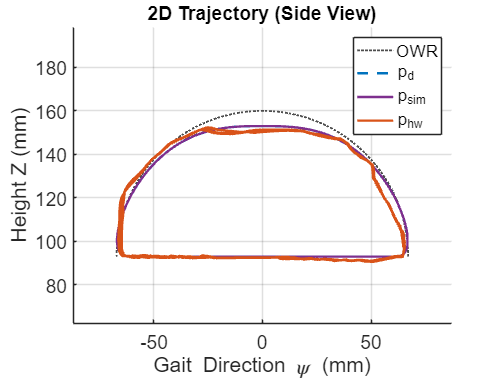

Salvato: ..\TESI\images3\gait_z_psi.pdf



if save_figures && ~exist(save_path, 'dir')
    mkdir(save_path);
end

% Stile Grafico
fig_size_4x1  = [100, 100, 1100, 900]; 
fig_size_square = [100, 100, 600, 600];
plot_fontsize_base = 16;  
plot_fontsize_title = 16; 
plot_linewidth = 2;

col_cmd   = [0 0.4470 0.7410]; 
col_sim   = [0.4940 0.1840 0.5560]; 
col_hw    = [0.8500 0.3250 0.0980]; 
col_lim   = [0.6350 0.0780 0.1840]; 
col_ideal = [0.3 0.3 0.3]; 
col_obs   = [0.7 0.7 0.7]; 
col_full  = [0.4660 0.6740 0.1880];

t_opts_time = {'LineWidth', plot_linewidth};
t_opts_track = {'Marker', '.', 'LineStyle', 'none'};


%% 4. PLOT 2D (Z vs Psi)
f = figure('Name', '2D Trajectory');
hold on; grid on; axis equal;
set(gca, 'FontSize', plot_fontsize_base);

% OWR
y_c = 0; z_c = 93; r = 67; th = linspace(0, pi, 100);
plot(y_c + r*cos(th), z_c + r*sin(th), ':', 'Color', [0.3 0.3 0.3], 'LineWidth', 1.5, 'DisplayName', 'OWR');

plot_has_data = false;
if isfield(data, 'cs_cmd'), plot(data.cs_cmd(3,:), data.cs_cmd(4,:), '--', 'Color', col_cmd, 'LineWidth', 2, 'DisplayName', 'p_d'); plot_has_data=true; end
if isfield(data, 'cs_sim'), plot(data.cs_sim(3,:), data.cs_sim(4,:), '-', 'Color', col_sim, 'LineWidth', 2, 'DisplayName', 'p_{sim}'); plot_has_data=true; end
if isfield(data, 'cs_hw'),  plot(data.cs_hw(3,:), data.cs_hw(4,:), '-', 'Color', col_hw, 'LineWidth', 2, 'DisplayName', 'p_{hw}'); plot_has_data=true; end

xlabel('Gait Direction \psi (mm)'); ylabel('Height Z (mm)');
title('2D Trajectory (Side View)', 'FontSize', plot_fontsize_title);
legend('show', 'Location', 'northeast');

if plot_has_data && isfield(data, 'cs_sim')
    xl = xlim; yl = ylim;
    xlim([xl(1)-20, xl(2)+20]); ylim([yl(1)-10, yl(2)+20]);
end

% --- Salvataggio Crop Perfetto ---
if save_figures
    filename = fullfile(save_path, 'gait_z_psi.pdf');
    set(f, 'Units', 'centimeters'); 
    pos = get(f, 'Position');
    set(f, 'PaperUnits', 'centimeters');
    set(f, 'PaperSize', [pos(3) pos(4)]);
    set(f, 'PaperPosition', [0 0 pos(3) pos(4)]); % Forza riempimento totale
    print(f, filename, '-dpdf', '-painters');
    fprintf('Salvato: %s\n', filename);
end

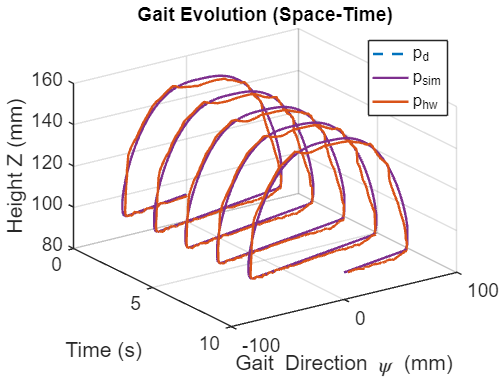

Salvato: ..\TESI\images3\gait_3d_spacetime.pdf


%% 3.5 PLOT 3D SPAZIO-TEMPO (Z-Psi-Time)
% Visualizza l'evoluzione temporale della falcata nello spazio 3D.

f3d = figure('Name', '3D Space-Time Trajectory');
hold on; grid on;
set(gca, 'FontSize', plot_fontsize_base);

% 1. Plot Traiettorie (X=Psi, Y=Time, Z=Height)
if isfield(data, 'cs_cmd') && ~isempty(data.cs_cmd)
    plot3(data.cs_cmd(3,:), data.cs_cmd(1,:), data.cs_cmd(4,:), ...
        '--', 'Color', col_cmd, 'LineWidth', 2, 'DisplayName', 'p_d');
end
if isfield(data, 'cs_sim') && ~isempty(data.cs_sim)
    plot3(data.cs_sim(3,:), data.cs_sim(1,:), data.cs_sim(4,:), ...
        '-', 'Color', col_sim, 'LineWidth', 2, 'DisplayName', 'p_{sim}');
end
if isfield(data, 'cs_hw') && ~isempty(data.cs_hw)
    plot3(data.cs_hw(3,:), data.cs_hw(1,:), data.cs_hw(4,:), ...
        '-', 'Color', col_hw, 'LineWidth', 2, 'DisplayName', 'p_{hw}');
end


% Formattazione
xlabel('Gait Direction \psi (mm)');
ylabel('Time (s)');
zlabel('Height Z (mm)');
title('Gait Evolution (Space-Time)', 'FontSize', plot_fontsize_title);

view(-35, 30); % Vista isometrica
set(gca, 'YDir', 'reverse'); % Tempo scorre "avanti"
legend('show', 'Location', 'best');

% Salvataggio Crop Perfetto
if save_figures
    filename = fullfile(save_path, 'gait_3d_spacetime.pdf');
    set(f3d, 'Units', 'centimeters'); 
    pos = get(f3d, 'Position');
    set(f3d, 'PaperUnits', 'centimeters');
    set(f3d, 'PaperSize', [pos(3) pos(4)]);
    set(f3d, 'PaperPosition', [0 0 pos(3) pos(4)]); 
    print(f3d, filename, '-dpdf', '-painters');
    fprintf('Salvato: %s\n', filename);
end

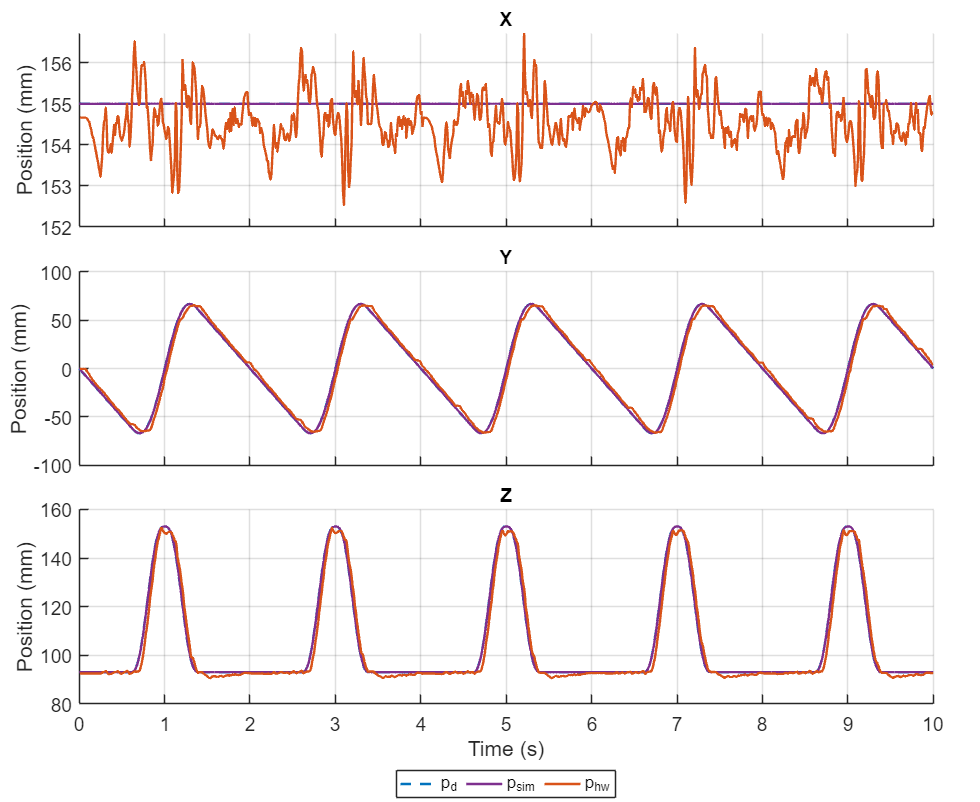


%% 5. ANALISI CARTESIANA (Traiettorie ed Errori)
% --- FIGURA 1: TRAIETTORIE ---
f_traj = figure('Name', 'Cartesian Traj', 'Position', fig_size_4x1);
tl = tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
titles = {'X', 'Y', 'Z'};
h_leg = [];

for i = 1:3
    ax = nexttile; hold(ax, 'on'); grid(ax, 'on'); set(ax, 'FontSize', plot_fontsize_base);
    if isfield(data, 'cs_cmd'), p=plot(ax, data.cs_cmd(1,:), data.cs_cmd(i+1,:), '--', 'Color', col_cmd, t_opts_time{:},'LineWidth', 2, 'DisplayName', 'p_d'); if i==1, h_leg=[h_leg,p]; end, end
    if isfield(data, 'cs_sim'), p=plot(ax, data.cs_sim(1,:), data.cs_sim(i+1,:), '-', 'Color', col_sim, t_opts_time{:},'LineWidth', 2, 'DisplayName', 'p_{sim}'); if i==1, h_leg=[h_leg,p]; end, end
    if isfield(data, 'cs_hw'),  p=plot(ax, data.cs_hw(1,:), data.cs_hw(i+1,:), '-', 'Color', col_hw, t_opts_time{:},'LineWidth', 2, 'DisplayName', 'p_{hw}'); if i==1, h_leg=[h_leg,p]; end, end
    ylabel(ax, 'Position (mm)'); title(ax, titles{i}, 'FontSize', plot_fontsize_title);
    if i<3, set(ax, 'XTickLabel', []); else, xlabel(ax, 'Time (s)'); end
end
linkaxes(findobj(f_traj, 'Type', 'Axes'), 'x');
if ~isempty(h_leg), lgd=legend(h_leg); lgd.Layout.Tile='South'; lgd.Orientation='horizontal'; end

% --- Salvataggio Crop Perfetto ---
if save_figures
    filename = fullfile(save_path, 'cartesian_trajectories.pdf');
    set(f_traj, 'Units', 'centimeters'); 
    pos = get(f_traj, 'Position');
    set(f_traj, 'PaperUnits', 'centimeters');
    set(f_traj, 'PaperSize', [pos(3) pos(4)]);
    set(f_traj, 'PaperPosition', [0 0 pos(3) pos(4)]); 
    print(f_traj, filename, '-dpdf', '-painters');
end

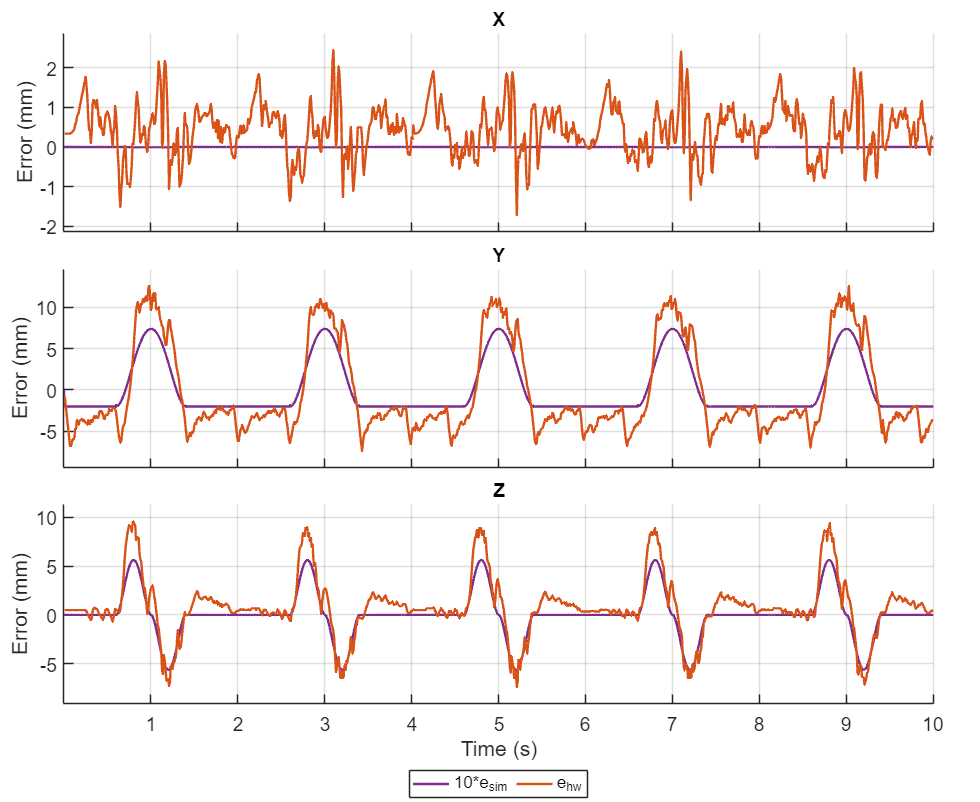


% --- FIGURA 2: ERRORI ---
f_err = figure('Name', 'Cartesian Errors', 'Position', fig_size_4x1);
tl = tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
titles_e = {'X', 'Y', 'Z'};
h_leg = [];

for i = 1:3
    ax = nexttile; hold(ax, 'on'); grid(ax, 'on'); set(ax, 'FontSize', plot_fontsize_base);
    if isfield(data, 'cs_cmd') && isfield(data, 'cs_sim')
        t = data.cs_sim(1,:); cmd = interp1(data.cs_cmd(1,:), data.cs_cmd(i+1,:), t);
        p=plot(ax, t, 10*(cmd - data.cs_sim(i+1,:)), '-', 'Color', col_sim, 'LineWidth', 2, 'DisplayName', '10*e_{sim}');
        if i==1, h_leg=[h_leg,p]; end
    end
    if isfield(data, 'cs_cmd') && isfield(data, 'cs_hw')
        t = data.cs_hw(1,:); cmd = interp1(data.cs_cmd(1,:), data.cs_cmd(i+1,:), t);
        p=plot(ax, t, cmd - data.cs_hw(i+1,:), '-', 'Color', col_hw, 'LineWidth', 2, 'DisplayName', 'e_{hw}');
        if i==1, h_leg=[h_leg,p]; end
    end
    ylabel(ax, 'Error (mm)'); title(ax, titles_e{i}, 'FontSize', plot_fontsize_title);
    axis(ax, 'tight'); yl=ylim(ax); r=yl(2)-yl(1); if r<1e-3, r=1; end
    ylim(ax, [yl(1)-0.1*r, yl(2)+0.1*r]);
    if i<3, set(ax, 'XTickLabel', []); else, xlabel(ax, 'Time (s)'); end
end
linkaxes(findobj(f_err, 'Type', 'Axes'), 'x');
if ~isempty(h_leg), lgd=legend(h_leg); lgd.Layout.Tile='South'; lgd.Orientation='horizontal'; end

% --- Salvataggio Crop Perfetto ---
if save_figures
    filename = fullfile(save_path, 'cartesian_errors.pdf');
    set(f_err, 'Units', 'centimeters'); 
    pos = get(f_err, 'Position');
    set(f_err, 'PaperUnits', 'centimeters');
    set(f_err, 'PaperSize', [pos(3) pos(4)]);
    set(f_err, 'PaperPosition', [0 0 pos(3) pos(4)]); 
    print(f_err, filename, '-dpdf', '-painters');
end

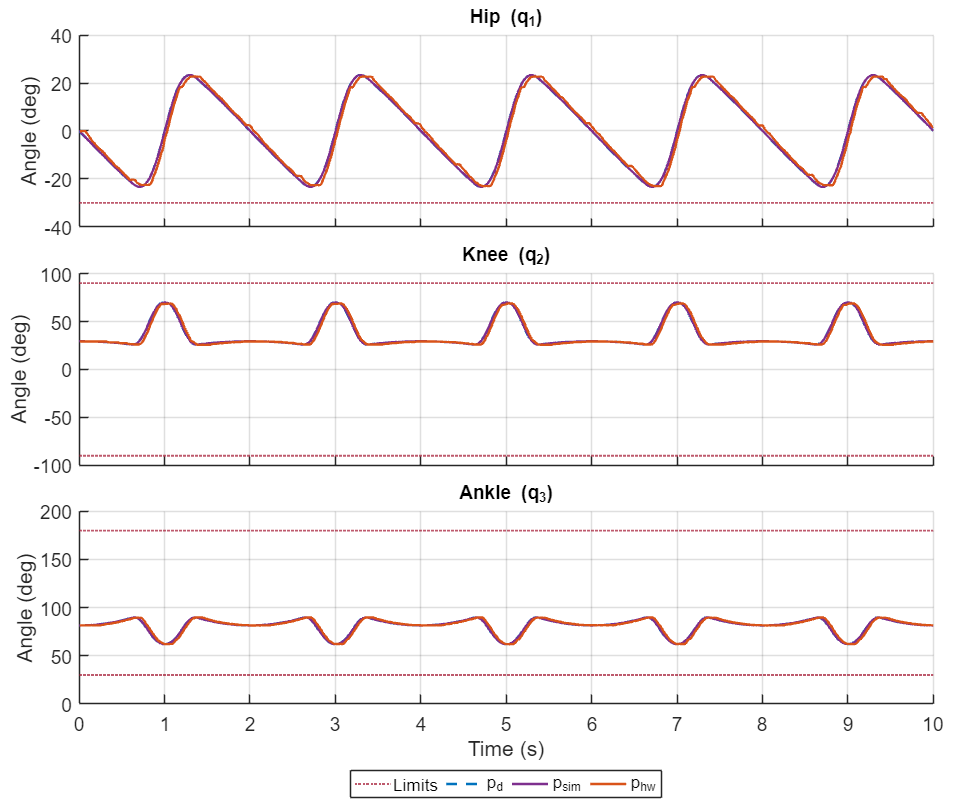



%% 6. ANALISI GIUNTI (Traiettorie ed Errori)
% --- FIGURA 1: TRAIETTORIE ---
f_j_traj = figure('Name', 'Joint Traj', 'Position', fig_size_4x1);
tl = tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
titles = {'Hip (q_1)', 'Knee (q_2)', 'Ankle (q_3)'};
flds = {'q1', 'q2', 'q3'};
h_leg = [];

for i = 1:3
    ax = nexttile; hold(ax, 'on'); grid(ax, 'on'); set(ax, 'FontSize', plot_fontsize_base);
    % Limiti
    if isfield(joint_limits, flds{i})
        l = yline(ax, joint_limits.(flds{i}), ':', 'Color', col_lim, 'LineWidth', 1.5, 'DisplayName', 'Limits');
        if i==1, h_leg=[h_leg, l(1)]; end
    end
    % Dati
    if isfield(data, 'js_cmd'), p=plot(ax, data.js_cmd(1,:), data.js_cmd(i+1,:), '--', 'Color', col_cmd, t_opts_time{:}, 'LineWidth', 2, 'DisplayName', 'p_d'); if i==1, h_leg=[h_leg,p]; end, end
    if isfield(data, 'js_sim'), p=plot(ax, data.js_sim(1,:), data.js_sim(i+1,:), '-', 'Color', col_sim, t_opts_time{:}, 'LineWidth', 2, 'DisplayName', 'p_{sim}'); if i==1, h_leg=[h_leg,p]; end, end
    if isfield(data, 'js_hw'),  p=plot(ax, data.js_hw(1,:), data.js_hw(i+1,:), '-', 'Color', col_hw, t_opts_time{:}, 'LineWidth', 2, 'DisplayName', 'p_{hw}'); if i==1, h_leg=[h_leg,p]; end, end
    
    ylabel(ax, 'Angle (deg)'); title(ax, titles{i}, 'FontSize', plot_fontsize_title);
    if i<3, set(ax, 'XTickLabel', []); else, xlabel(ax, 'Time (s)'); end
end
linkaxes(findobj(f_j_traj, 'Type', 'Axes'), 'x');
if ~isempty(h_leg), lgd=legend(h_leg); lgd.Layout.Tile='South'; lgd.Orientation='horizontal'; end

% --- Salvataggio Crop Perfetto ---
if save_figures
    filename = fullfile(save_path, 'joint_trajectories.pdf');
    set(f_j_traj, 'Units', 'centimeters'); 
    pos = get(f_j_traj, 'Position');
    set(f_j_traj, 'PaperUnits', 'centimeters');
    set(f_j_traj, 'PaperSize', [pos(3) pos(4)]);
    set(f_j_traj, 'PaperPosition', [0 0 pos(3) pos(4)]); 
    print(f_j_traj, filename, '-dpdf', '-painters');
end

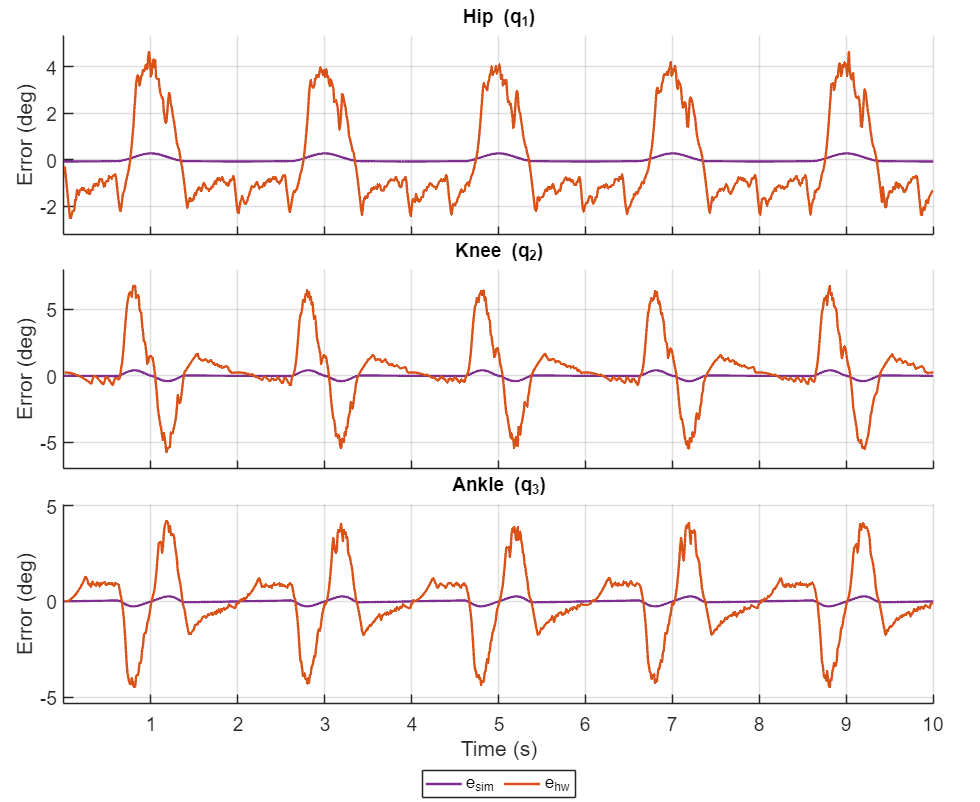



% --- FIGURA 2: ERRORI ---
f_j_err = figure('Name', 'Joint Errors', 'Position', fig_size_4x1);
tl = tiledlayout(3, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
titles = {'Hip (q_1)', 'Knee (q_2)', 'Ankle (q_3)'};
h_leg = [];

for i = 1:3
    ax = nexttile; hold(ax, 'on'); grid(ax, 'on'); set(ax, 'FontSize', plot_fontsize_base);
    
    if isfield(data, 'js_cmd') && isfield(data, 'js_sim')
        t = data.js_sim(1,:);
        cmd = interp1(data.js_cmd(1,:), data.js_cmd(i+1,:), t);
        err = cmd - data.js_sim(i+1,:);
        p=plot(ax, t, err, '-', 'Color', col_sim, 'LineWidth', 2, 'DisplayName', 'e_{sim}');
        if i==1, h_leg=[h_leg,p]; end
    end
    if isfield(data, 'js_cmd') && isfield(data, 'js_hw')
        t = data.js_hw(1,:);
        cmd = interp1(data.js_cmd(1,:), data.js_cmd(i+1,:), t);
        err = cmd - data.js_hw(i+1,:);
        p=plot(ax, t, err, '-', 'Color', col_hw, 'LineWidth', 2, 'DisplayName', 'e_{hw}');
        if i==1, h_leg=[h_leg,p]; end
    end
    
    ylabel(ax, 'Error (deg)'); title(ax, titles{i}, 'FontSize', plot_fontsize_title);
    axis(ax, 'tight'); yl=ylim(ax); r=yl(2)-yl(1); if r<1e-3, r=1; end
    ylim(ax, [yl(1)-0.1*r, yl(2)+0.1*r]);
    if i<3, set(ax, 'XTickLabel', []); else, xlabel(ax, 'Time (s)'); end
end
linkaxes(findobj(f_j_err, 'Type', 'Axes'), 'x');
if ~isempty(h_leg), lgd=legend(h_leg); lgd.Layout.Tile='South'; lgd.Orientation='horizontal'; end

% --- Salvataggio Crop Perfetto ---
if save_figures
    filename = fullfile(save_path, 'joint_errors.pdf');
    set(f_j_err, 'Units', 'centimeters'); 
    pos = get(f_j_err, 'Position');
    set(f_j_err, 'PaperUnits', 'centimeters');
    set(f_j_err, 'PaperSize', [pos(3) pos(4)]);
    set(f_j_err, 'PaperPosition', [0 0 pos(3) pos(4)]); 
    print(f_j_err, filename, '-dpdf', '-painters');
end

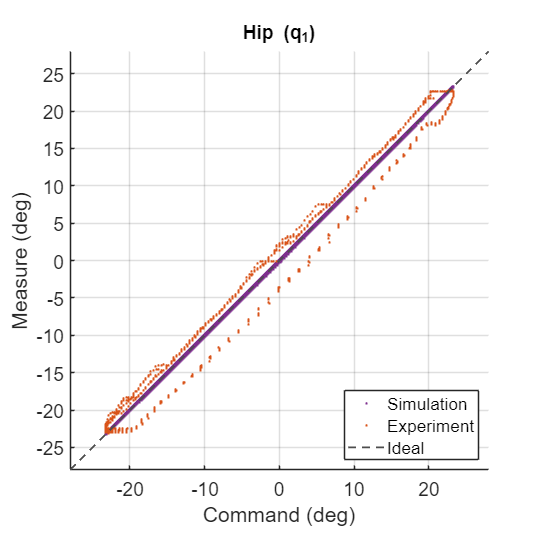

Salvato: q_track_1.pdf


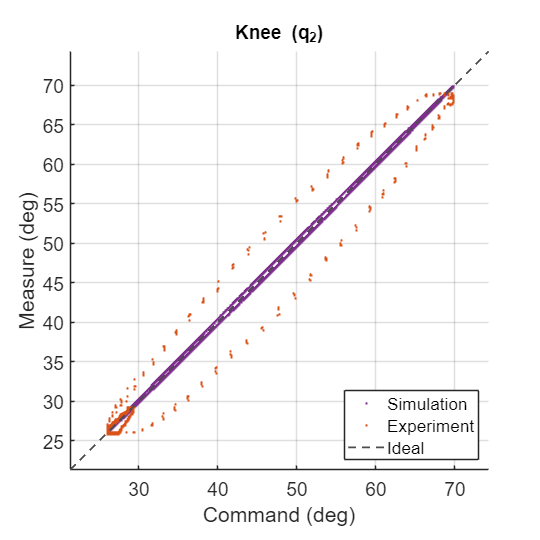

Salvato: q_track_2.pdf


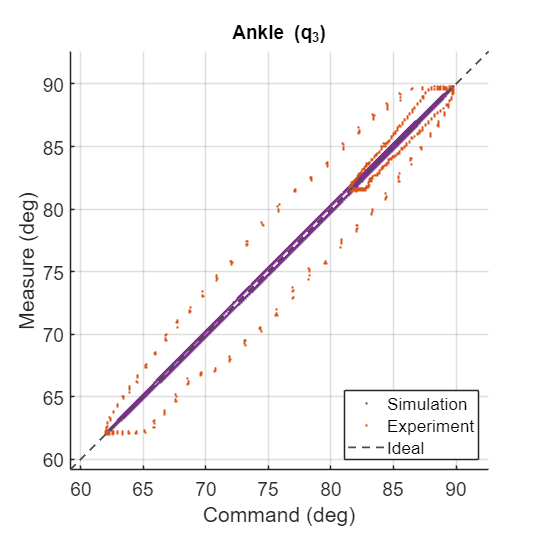

Salvato: q_track_3.pdf




%% 7. PLOT TRACKING (Separate Figures)
titles_track = {'Hip (q_1)', 'Knee (q_2)', 'Ankle (q_3)'};
file_names   = {'q_track_1.pdf', 'q_track_2.pdf', 'q_track_3.pdf'};

for i = 1:3
    f = figure('Name', titles_track{i}, 'Position', fig_size_square);
    hold on; grid on; axis equal; set(gca, 'FontSize', plot_fontsize_base);
    
    min_val = inf; max_val = -inf;
    plot_something = false;
    
    % Sim vs Cmd
    if isfield(data, 'js_cmd') && isfield(data, 'js_sim')
        t_sim = data.js_sim(1, :); 
        q_cmd_interp = interp1(data.js_cmd(1,:), data.js_cmd(i+1,:), t_sim);
        q_sim = data.js_sim(i+1,:);
        plot(q_cmd_interp, q_sim, t_opts_track{:}, 'Color', col_sim, 'DisplayName', 'Simulation');
        min_val = min([min_val, min(q_sim), min(q_cmd_interp)]);
        max_val = max([max_val, max(q_sim), max(q_cmd_interp)]);
        plot_something = true;
    end
    
    % HW vs Cmd
    if isfield(data, 'js_cmd') && isfield(data, 'js_hw')
        t_hw = data.js_hw(1, :);
        q_cmd_interp = interp1(data.js_cmd(1,:), data.js_cmd(i+1,:), t_hw);
        q_hw = data.js_hw(i+1,:);
        plot(q_cmd_interp, q_hw, t_opts_track{:}, 'Color', col_hw, 'DisplayName', 'Experiment');
        min_val = min([min_val, min(q_hw), min(q_cmd_interp)]);
        max_val = max([max_val, max(q_hw), max(q_cmd_interp)]);
        plot_something = true;
    end
    
    % Ideal
    if plot_something
        range = max_val - min_val; if range < 1e-3, range = 1; end
        m = range * 0.1; lims = [min_val - m, max_val + m];
        plot(lims, lims, '--', 'Color', col_ideal, 'LineWidth', 1.5, 'DisplayName', 'Ideal');
        xlim(lims); ylim(lims);
    end
    
    xlabel('Command (deg)'); ylabel('Measure (deg)'); title(titles_track{i}, 'FontSize', plot_fontsize_title);
    legend('show', 'Location', 'southeast');
    
    % --- Salvataggio Crop Perfetto ---
    if save_figures
        filename = fullfile(save_path, file_names{i});
        set(f, 'Units', 'centimeters'); 
        pos = get(f, 'Position');
        set(f, 'PaperUnits', 'centimeters');
        set(f, 'PaperSize', [pos(3) pos(4)]);
        set(f, 'PaperPosition', [0 0 pos(3) pos(4)]); 
        print(f, filename, '-dpdf', '-painters');
        fprintf('Salvato: %s\n', file_names{i});
    end
end

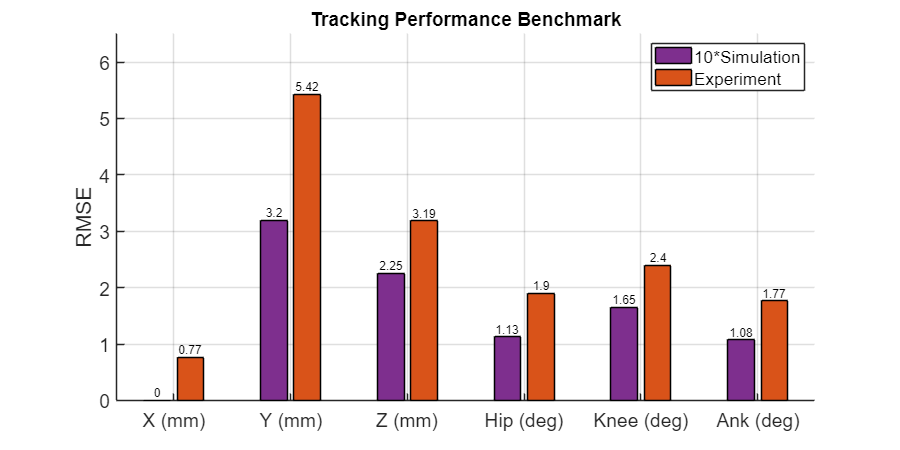

Salvato: ..\TESI\images3\rmse_benchmark.pdf




%% 8. RMSE & BENCHMARK
rmse_cs_sim = zeros(1,3); rmse_cs_hw = zeros(1,3);
rmse_js_sim = zeros(1,3); rmse_js_hw = zeros(1,3);

% Cartesiano (mm)
for i=1:3
    if isfield(data,'cs_cmd') && isfield(data,'cs_sim')
        t=data.cs_sim(1,:); cmd=interp1(data.cs_cmd(1,:), data.cs_cmd(i+1,:), t);
        rmse_cs_sim(i) = sqrt(mean((cmd - data.cs_sim(i+1,:)).^2));
    end
    if isfield(data,'cs_cmd') && isfield(data,'cs_hw')
        t=data.cs_hw(1,:); cmd=interp1(data.cs_cmd(1,:), data.cs_cmd(i+1,:), t);
        rmse_cs_hw(i) = sqrt(mean((cmd - data.cs_hw(i+1,:)).^2));
    end
end

% Giunti (Gradi)
for i=1:3
    if isfield(data,'js_cmd') && isfield(data,'js_sim')
        t=data.js_sim(1,:); cmd=interp1(data.js_cmd(1,:), data.js_cmd(i+1,:), t);
        rmse_js_sim(i) = sqrt(mean((cmd - data.js_sim(i+1,:)).^2));
    end
    if isfield(data,'js_cmd') && isfield(data,'js_hw')
        t=data.js_hw(1,:); cmd=interp1(data.js_cmd(1,:), data.js_cmd(i+1,:), t);
        rmse_js_hw(i) = sqrt(mean((cmd - data.js_hw(i+1,:)).^2));
    end
end

% Plot RMSE
rmse_cs_sim = 10*rmse_cs_sim;
rmse_js_sim = 10*rmse_js_sim;

f_rmse = figure('Name', 'RMSE Benchmark', 'Position', [100, 100, 1000, 500]);
hold on; grid on; set(gca, 'FontSize', plot_fontsize_base);

y_data = [[rmse_cs_sim, rmse_js_sim]; [rmse_cs_hw, rmse_js_hw]]';
b = bar(y_data, 'grouped');
b(1).FaceColor = col_sim; b(1).DisplayName = '10*Simulation';
b(2).FaceColor = col_hw;  b(2).DisplayName = 'Experiment';

ylabel('RMSE'); title('Tracking Performance Benchmark', 'FontSize', 16);
legend('show', 'Location', 'northeast');
set(gca, 'XTick', 1:6, 'XTickLabel', {'X (mm)', 'Y (mm)', 'Z (mm)', 'Hip (deg)', 'Knee (deg)', 'Ank (deg)'});

for i = 1:length(b)
    xtips = b(i).XEndPoints; ytips = b(i).YEndPoints;
    labels = string(round(b(i).YData, 2));
    labels(strcmp(labels, "NaN")) = ""; 
    text(xtips, ytips, labels, 'HorizontalAlignment', 'center', 'VerticalAlignment', 'bottom', 'FontSize', 10);
end
ylim([0, max(max(y_data))*1.2]);

% --- Salvataggio Crop Perfetto ---
if save_figures
    filename = fullfile(save_path, 'rmse_benchmark.pdf');
    set(f_rmse, 'Units', 'centimeters'); 
    pos = get(f_rmse, 'Position');
    set(f_rmse, 'PaperUnits', 'centimeters');
    set(f_rmse, 'PaperSize', [pos(3) pos(4)]);
    set(f_rmse, 'PaperPosition', [0 0 pos(3) pos(4)]); 
    print(f_rmse, filename, '-dpdf', '-painters');
    fprintf('Salvato: %s\n', filename);
end

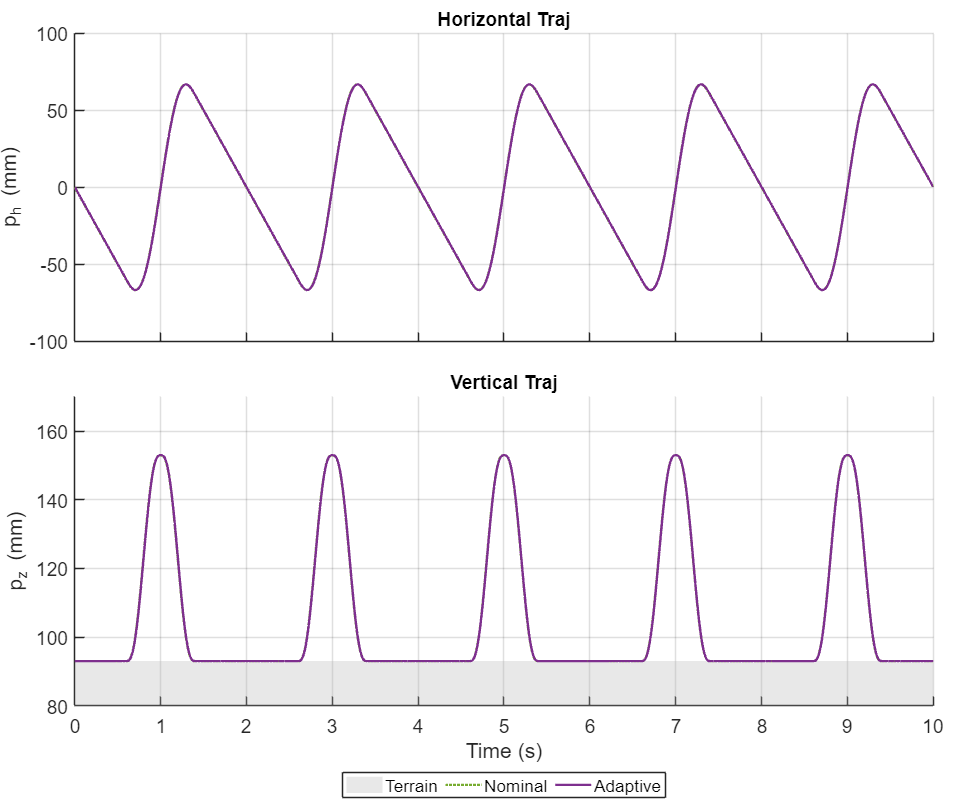

Salvato: ..\TESI\images3\adaptive_comparison.pdf




%% 9. ADAPTIVE COMPARISON (8)
if save_figures && isfield(data, 'cs_full')
    f_adapt = figure('Name', 'Adaptive Trajectory', 'Position', fig_size_4x1);
    tl = tiledlayout(2, 1, 'TileSpacing', 'compact', 'Padding', 'compact');
    
    ax1 = nexttile; hold(ax1, 'on'); grid(ax1, 'on'); set(ax1, 'FontSize', plot_fontsize_base);
    if isfield(data, 'cs_full'), plot(ax1, data.cs_full(1,:), data.cs_full(3,:), ':', 'Color', col_full, 'LineWidth', 2, 'DisplayName', 'Nominal'); end
    if isfield(data, 'cs_sim'), plot(ax1, data.cs_sim(1,:), data.cs_sim(3,:), '-', 'Color', col_sim, 'LineWidth', 2, 'DisplayName', 'Adaptive'); end
    ylabel(ax1, 'p_h (mm)'); title(ax1, 'Horizontal Traj', 'FontSize', plot_fontsize_title);
    
    ax2 = nexttile; hold(ax2, 'on'); grid(ax2, 'on'); set(ax2, 'FontSize', plot_fontsize_base);
    if isfield(data, 'obstacle')
         t_o=data.obstacle(1,:); z_o=data.obstacle(2,:);
         area(ax2, t_o, z_o, 'FaceColor', col_obs, 'FaceAlpha', 0.3, 'EdgeColor', 'none', 'DisplayName', 'Terrain');
    end
    if isfield(data, 'cs_full'), plot(ax2, data.cs_full(1,:), data.cs_full(4,:), ':', 'Color', col_full, 'LineWidth', 2, 'DisplayName', 'Nominal'); end
    if isfield(data, 'cs_sim'), plot(ax2, data.cs_sim(1,:), data.cs_sim(4,:), '-', 'Color', col_sim, 'LineWidth', 2, 'DisplayName', 'Adaptive'); end
    ylabel(ax2, 'p_z (mm)'); xlabel(ax2, 'Time (s)'); title(ax2, 'Vertical Traj', 'FontSize', plot_fontsize_title);
    
    linkaxes([ax1, ax2], 'x'); set(ax1, 'XTickLabel', []);
    lgd = legend(ax2); lgd.Layout.Tile='South'; lgd.Orientation='horizontal';
    ylim([80,170]);

    % Salvataggio
    filename = fullfile(save_path, 'adaptive_comparison.pdf');
    set(f_adapt, 'Units', 'centimeters'); 
    pos = get(f_adapt, 'Position');
    set(f_adapt, 'PaperUnits', 'centimeters');
    set(f_adapt, 'PaperSize', [pos(3) pos(4)]);
    set(f_adapt, 'PaperPosition', [0 0 pos(3) pos(4)]); 
    print(f_adapt, filename, '-dpdf', '-painters');
    fprintf('Salvato: %s\n', filename);
end


fprintf('Fatto.\n');

Fatto.
